#                 Antenna Array Processing

##                                            HW3

                 Mohammadreza Arani         :::::::::::::         810100511

                                                            1401/08/13                                         

clear; clc; close all;

### Q1:

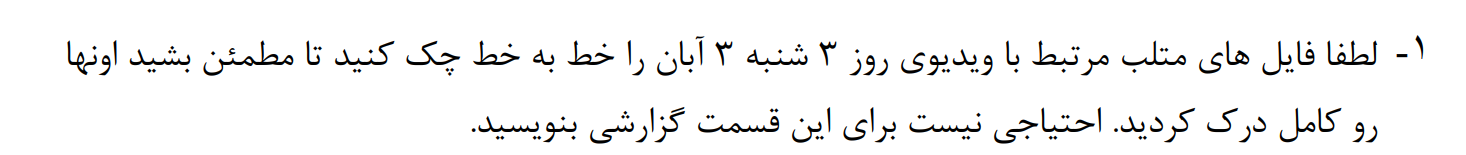

An MLX file is prepared to show that codes are checked line by line and the result is depicted in each section.

### Q2:

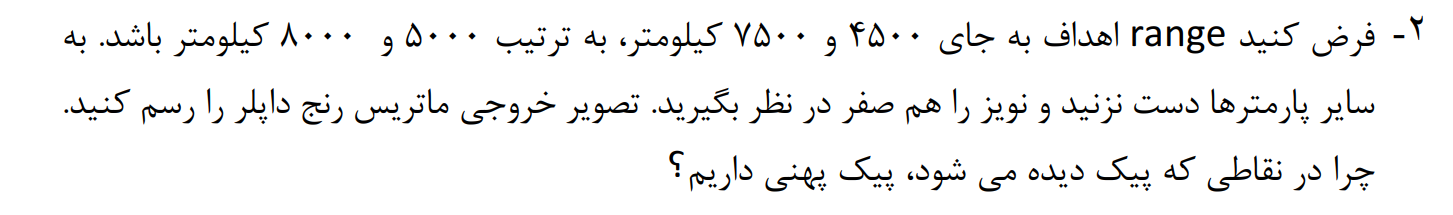

% We have to change Ranges of the target and consider a noise-free
% enviroment ---> using given Code and changing some parameters;

% Signals are considered to be in Low Frequency Band
ts =  1e-2; % --> 10 ms
fs=1/ts; % sampling rate --> 100Hz
C=300e6; % light speed

tau_num=1;  % --> Consider a single sample on the signal
tau=tau_num*ts; % --> the signal length would be equal to number of samples multiplied by length of each sample!

PRI=1e-1;
PRI_num=round(PRI/ts); % --> number of sqaured pulses in signal

PRF=1/PRI;

Trecording=1;   % --> Recording time at the receiver!

deltaf=1/Trecording; % Frequency Resolution

pulse_num=round(Trecording/PRI); % Number of pulse in recording time
sample_num=round(Trecording/ts);

t=0:ts:Trecording-ts; % Time Vector 
freq=-fs/2:deltaf:fs/2-deltaf; % Frequency Vector

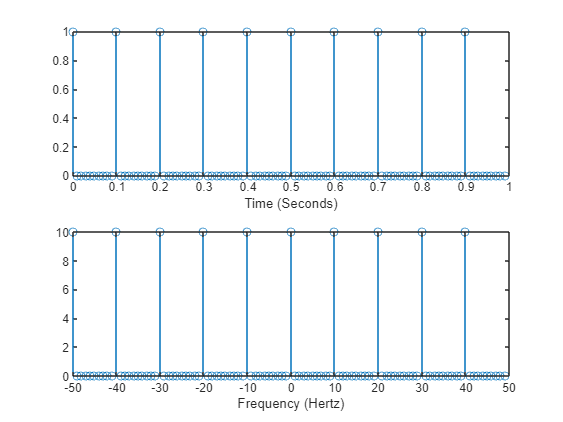

% Create Our Signal : The one Pulse:
SL_PRI=[ones(1,tau_num) zeros(1,PRI_num-tau_num)]; % single pulse in the interval of sending and receiving
sl=repmat(SL_PRI,1,pulse_num); % Repeated pulse for each PRI in Trecording

figure(1)
subplot(2,1,1)
stem(t,sl) % The Signal itself --> Pulse Train
xlabel('Time (Seconds)')

subplot(2,1,2)
slf=fftshift(fft(sl)); % shifted fft signal --> Fourier transformation --> I expect to see the sampled form of the expected Fourier transform with the distance of 1/PRI = PRF
stem(freq,abs(slf)) % Frequency Domain
xlabel('Frequency (Hertz)')

#### Target-1:

delay_Target1=round(5/1.5)*ts;
R_Target1=C/2*delay_Target1;  %R=5000 KM
fd_Target1=-2*deltaf;    % fd= -2 Hz
beta_Target1=0.2; % Attenuation Factor!
% Receiving signal:
% y =  b*dopplershift*sl(t-td)
y_Target1=beta_Target1*exp(1j*2*pi*fd_Target1*t).*circshift(sl,delay_Target1/ts);  % Shifting the signal for 3 slots using circshift

#### Target-2:

delay_Target2=round(8/1.5)*ts;
R_Target2=C/2*delay_Target2; % R=8000 KM
fd_Target2=3*deltaf;    % fd=3 Hz
beta_Target2=0.5;
% Receiving signal:
% y =  b*dopplershift*sl(t-td)
y_Target2=beta_Target2*exp(1j*2*pi*fd_Target2*t).*circshift(sl,delay_Target2/ts);  % Shifting the signal for 5 slots using circshift

Let's see the time domain signals:

figure(2)
subplot(2,1,1)
stem(t,sl)
hold on
stem(t,abs(y_Target1),'r')
stem(t,abs(y_Target2),'g')
xlabel('Time (Seconds)')

Also, the Frequency domain of received signals:

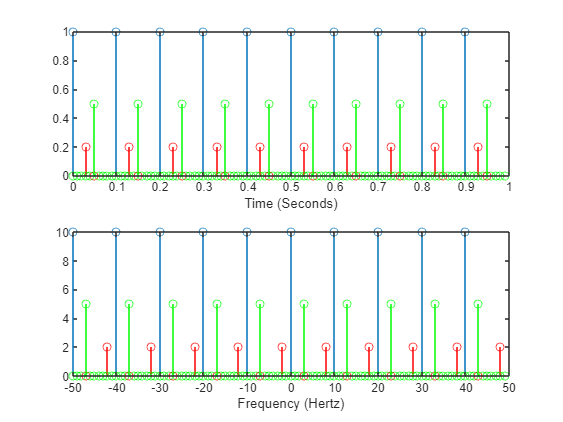


subplot(2,1,2)
yf_Target1=fftshift(fft(y_Target1));
yf_Target2=fftshift(fft(y_Target2));
stem(freq,abs(slf))
hold on
stem(freq,abs(yf_Target1),'r')
stem(freq,abs(yf_Target2),'g')
xlabel('Frequency (Hertz)')

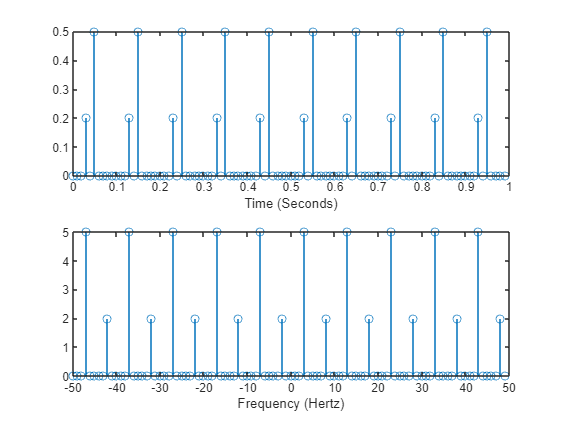

figure(3)
y=y_Target1+y_Target2;
yf=fftshift(fft(y)); 


subplot(2,1,1)
stem(t,abs(y)) % Total signal Time domain
xlabel('Time (Seconds)')

subplot(2,1,2)
stem(freq,abs(yf)) % Total signal Frequency domain
xlabel('Frequency (Hertz)')

## Range Doppler Processing:

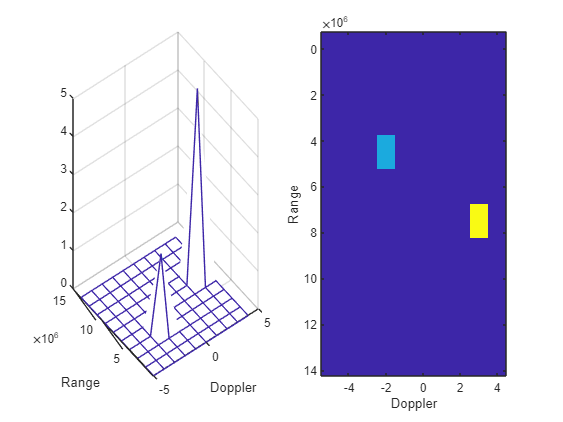

yff=circshift(yf,PRF/2/deltaf); % Shifting the Frequency domain so that the 0 doppler carrier will be shifted to -PRF/2 as the starting point
yf_reshape=reshape(yff,PRF/deltaf,sample_num*deltaf/PRF).'; % Now starting from -PRF/2, take PRF size data (PRF/deltaf)
 % Creating the conjugate of the signal to multiply to yf
SL_PRIf=fftshift(fft(SL_PRI)).';
SL_PRIff=circshift(SL_PRIf,PRF/2/deltaf);

BASE=repmat(conj(SL_PRIff),1,PRF/deltaf); % Conjugate of Base signal to multiply to yf
COEFICIENTS=ifft(yf_reshape.*BASE); % Each Column of yf is multiplied to each column of Base signal

figure(4)
subplot(1,2,1)
RANGE=C/2*(0:tau:PRI-tau);
DOPPLER=-PRF/2:deltaf:PRF/2-deltaf;
mesh(DOPPLER,RANGE,(abs(COEFICIENTS)))
ylabel('Range')
xlabel('Doppler')

subplot(1,2,2)
imagesc(DOPPLER,RANGE,(abs(COEFICIENTS)))
ylabel('Range')
xlabel('Doppler')

### Q3:

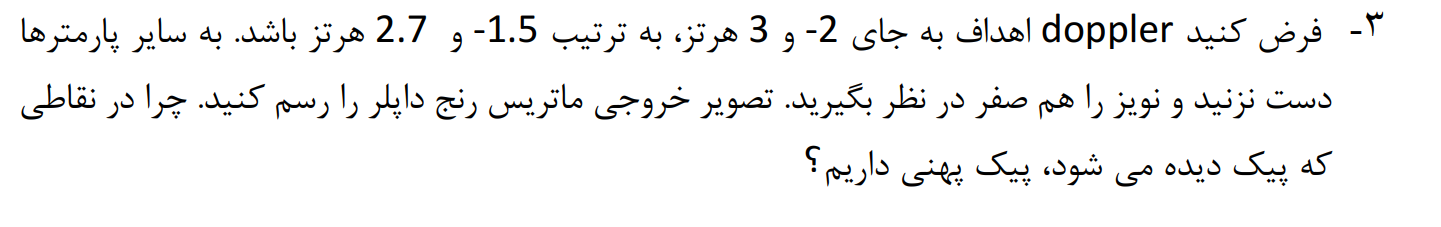

#### Target-1:

delay_Target1=round(5/1.5)*ts;
R_Target1=C/2*delay_Target1;  %R=4500 KM
fd_Target1=-1.5*deltaf;    % fd= -2 Hz
beta_Target1=0.2; % Attenuation Factor!
% Receiving signal:
% y =  b*dopplershift*sl(t-td)
y_Target1=beta_Target1*exp(1j*2*pi*fd_Target1*t).*circshift(sl,delay_Target1/ts);  % Shifting the signal for 3 slots using circshift

#### Target-2:

delay_Target2=round(8/1.5)*ts;
R_Target2=C/2*delay_Target2; % R=7500 KM
fd_Target2=2.7*deltaf;    % fd=3 Hz
beta_Target2=0.5;
% Receiving signal:
% y =  b*dopplershift*sl(t-td)
y_Target2=beta_Target2*exp(1j*2*pi*fd_Target2*t).*circshift(sl,delay_Target2/ts);  % Shifting the signal for 5 slots using circshift

Let's see the time domain signals:

figure(2)
subplot(2,1,1)
stem(t,sl)
hold on
stem(t,abs(y_Target1),'r')
stem(t,abs(y_Target2),'g')
xlabel('Time (Seconds)')

Also, the Frequency domain of received signals:

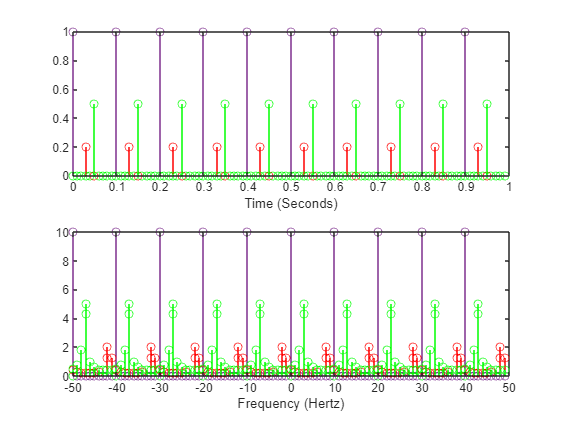


subplot(2,1,2)
yf_Target1=fftshift(fft(y_Target1));
yf_Target2=fftshift(fft(y_Target2));
stem(freq,abs(slf))
hold on
stem(freq,abs(yf_Target1),'r')
stem(freq,abs(yf_Target2),'g')
xlabel('Frequency (Hertz)')

We can detect the glitch/ disorder in frequency domain where we have nearly 3 peaks in 3 adjacent frequency bins! --> This is due to frequency resolution.

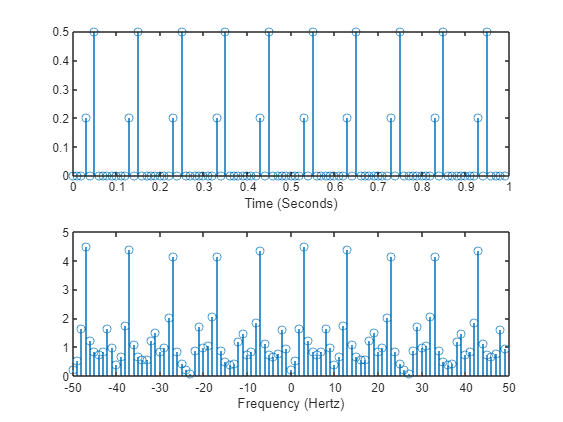

figure(3)
y=y_Target1+y_Target2;
yf=fftshift(fft(y)); 


subplot(2,1,1)
stem(t,abs(y)) % Total signal Time domain
xlabel('Time (Seconds)')

subplot(2,1,2)
stem(freq,abs(yf)) % Total signal Frequency domain
xlabel('Frequency (Hertz)')

Received signal is the summation/superposition of both targets! ===> in Time domain we can see targets are seperated with 0.2 and 0.5 amplitude and different positions at 0.5 and 0.3 indicating 0.5/0.1 =5 --> R = c/2 * 5*ts = 7500 Km ;  0.3/0.1 =3 --> R = c/2 * 3*ts = 4500 Km

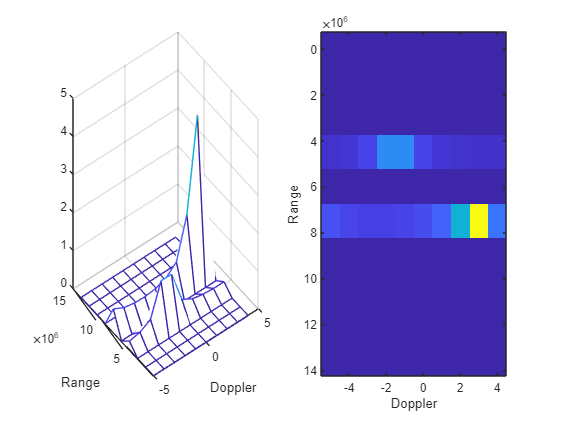

yff=circshift(yf,PRF/2/deltaf); % Shifting the Frequency domain so that the 0 doppler carrier will be shifted to -PRF/2 as the starting point
yf_reshape=reshape(yff,PRF/deltaf,sample_num*deltaf/PRF).'; % Now starting from -PRF/2, take PRF size data (PRF/deltaf)
 % Creating the conjugate of the signal to multiply to yf
SL_PRIf=fftshift(fft(SL_PRI)).';
SL_PRIff=circshift(SL_PRIf,PRF/2/deltaf);

BASE=repmat(conj(SL_PRIff),1,PRF/deltaf); % Conjugate of Base signal to multiply to yf
COEFICIENTS=ifft(yf_reshape.*BASE); % Each Column of yf is multiplied to each column of Base signal

figure(4)
subplot(1,2,1)
RANGE=C/2*(0:tau:PRI-tau);
DOPPLER=-PRF/2:deltaf:PRF/2-deltaf;
mesh(DOPPLER,RANGE,(abs(COEFICIENTS)))
ylabel('Range')
xlabel('Doppler')

subplot(1,2,2)
imagesc(DOPPLER,RANGE,(abs(COEFICIENTS)))
ylabel('Range')
xlabel('Doppler')

Above, we can see that due to the fact that 2.7 and 1.5 are not integer coefficient of delta_f (Frequency resolution) --> They are mapped into orthonormal basis and the result is that 2.7 is mapped to 2 , 3 Hz with 3 being the major power carrier and -1.5 is mapped to -2 , -1 Hz with both being equally distanced. --> The fact is when you are estimating the doppler, you cannot detect 2.7 Hz and what you detect is 3 Hz due to frequency resolution...

Also, when you have 2 equally spaced inetegr from a doppler frequency in this case, you cannot detect whether it was the lower or the higher doppler frequency.